## **Trim Input Variation Plot**

Helicopter Emergency Rescue (HER25)

***HER05**** Flight Mechanics, Performance & Control - Hanchen Li*

% Housekeeping
clear
clc
close all

### 0 Input

Manually input data from optimiser

**0.1 Data Point**

% Trim Point
v_F_t = 72.0222222; % 140 knots = 72.0222222 m/s

% Vertical Climb
% from 0 to 17.5566 m/s
v_C = [0, 2, 4, 6, 8, 10, 11.53];

% Forward Flight
% from 0 to 84.7 m/s
v_F = [0, 15, 30, 45, 60, v_F_t, 90.3];

**0.2 MTOW**

% Hover
theta_LR_H_1 = 0.2371;
theta_UR_H_1 = 0.2840;
theta_1s_H_1 = 0;
theta_1c_H_1 = 0;
phi_H_1      = 0;
theta_H_1    = 0;
delta_E_H_1  = 0;
delta_R_H_1  = 0;

% Trim Point
theta_LR_t_1 = 0.1760;
theta_UR_t_1 = 0.1764;
theta_1s_t_1 = -0.0688;
theta_1c_t_1 = -0.0369;
phi_t_1      = 0.0141;
theta_t_1    = 0.0095;
delta_E_t_1  = -0.0067;
delta_R_t_1  = 0.0020;

% Vertical Climb
theta_LR_C_1 = [theta_LR_H_1, 0.2520, 0.2689, 0.2877, 0.3084, 0.3307, 0.3489];
theta_UR_C_1 = [theta_UR_H_1, 0.2916, 0.2989, 0.3058, 0.3120, 0.3175, 0.3212];

% Forward Flight
theta_LR_F_1 = [theta_LR_H_1, 0.1815, 0.1900, 0.1791, 0.1706, theta_LR_t_1, 0.1963];
theta_UR_F_1 = [theta_UR_H_1, 0.1471, 0.1218, 0.1387, 0.1616, theta_UR_t_1, 0.2015];
theta_1s_F_1 = [theta_1s_H_1, -0.0641, -0.0509, -0.0530, -0.0609, theta_1s_t_1, -0.0837];
theta_1c_F_1 = [theta_1c_H_1, 0.0125, -0.0158, -0.0276, -0.0350, theta_1c_t_1, -0.0273];
phi_F_1      = [phi_H_1, 0.0105, 0.0290, 0.0249, 0.0157, phi_t_1, 0.0143];
theta_F_1    = [theta_H_1, 0.0598, -0.0065, -0.0124, 0.0039, theta_t_1, 0.0123];
delta_E_F_1  = [delta_E_H_1, -7.7478e-04, 3.7814e-04, 0.0021, -0.0023, delta_E_t_1, -0.0130];
delta_R_F_1  = [delta_R_H_1, 0.0493, 0.0172, 0.0057, 0.0025, delta_R_t_1, 0.0018];

**0.3 MZFW**

% Hover
theta_LR_H_2 = 0.2141;
theta_UR_H_2 = 0.2602;
theta_1s_H_2 = 0;
theta_1c_H_2 = 0;
phi_H_2      = 0;
theta_H_2    = 0;
delta_E_H_2  = 0;
delta_R_H_2  = 0;

% Trim Point
theta_LR_t_2 = 0.1716;
theta_UR_t_2 = 0.1546;
theta_1s_t_2 = -0.0543;
theta_1c_t_2 = -0.0295;
phi_t_2      = 0.0294;
theta_t_2    = -0.0127;
delta_E_t_2  = 1.0546e-04;
delta_R_t_2  = 4.5735e-04;

% Vertical Climb
theta_LR_C_2 = [theta_LR_H_2, 0.2294, 0.2468, 0.2662, 0.2876, 0.3108, 0.3297];
theta_UR_C_2 = [theta_UR_H_2, 0.2675, 0.2745, 0.2810, 0.2867, 0.2917, 0.2948];

% Forward Flight
theta_LR_F_2 = [theta_LR_H_2, 0.1875, 0.1727, 0.1626, 0.1667, theta_LR_t_2, 0.1933];
theta_UR_F_2 = [theta_UR_H_2, 0.1046, 0.1035, 0.1227, 0.1356, theta_UR_t_2, 0.1878];
theta_1s_F_2 = [theta_1s_H_2, -0.0483, -0.0381, -0.0403, -0.0458, theta_1s_t_2, -0.0710];
theta_1c_F_2 = [theta_1c_H_2, 0.0057, -0.0154, -0.0250, -0.0314, theta_1c_t_2, -0.0117];
phi_F_2      = [phi_H_2, 0.0244, 0.0353, 0.0316, 0.0349, phi_t_2, 0.0188];
theta_F_2    = [theta_H_2, 0.0199, -0.0260, -0.0245, -0.0285, theta_t_2, 0.0041];
delta_E_F_2  = [delta_E_H_2, -3.9828e-04, 0.0013, 0.0055, -6.4829e-05, delta_E_t_2, -0.0041];
delta_R_F_2  = [delta_R_H_2, 0.0012, -0.0015, -4.2132e-04, 3.0026e-04, delta_R_t_2, 6.6978e-04];

**0.4 Maximum Fuel with Zero Payload**

% Hover
theta_LR_H_3 = 0.2172;
theta_UR_H_3 = 0.2635;
theta_1s_H_3 = 0;
theta_1c_H_3 = 0;
phi_H_3      = 0;
theta_H_3    = 0;
delta_E_H_3  = 0;
delta_R_H_3  = 0;

% Trim Point
theta_LR_t_3 = 0.1716;
theta_UR_t_3 = 0.1573;
theta_1s_t_3 = -0.0556;
theta_1c_t_3 = -0.0307;
phi_t_3      = 0.0268;
theta_t_3    = -0.0088;
delta_E_t_3  = -0.0011;
delta_R_t_3  = 6.8261e-04;

% Vertical Climb
theta_LR_C_3 = [theta_LR_H_3, 0.2324, 0.2498, 0.2692, 0.2904, 0.3135, 0.3323];
theta_UR_C_3 = [theta_UR_H_3, 0.2708, 0.2779, 0.2844, 0.2902, 0.2952, 0.2985];

% Forward Flight
theta_LR_F_3 = [theta_LR_H_3, 0.1899, 0.1750, 0.1636, 0.1654, theta_LR_t_3, 0.1928];
theta_UR_F_3 = [theta_UR_H_3, 0.1073, 0.1059, 0.1258, 0.1404, theta_UR_t_3, 0.1890];
theta_1s_F_3 = [theta_1s_H_3, -0.0503, -0.0395, -0.0416, -0.0475, theta_1s_t_3, -0.0718];
theta_1c_F_3 = [theta_1c_H_3, 0.0065, -0.0155, -0.0253, -0.0318, theta_1c_t_3, -0.0143];
phi_F_3      = [phi_H_3, 0.0237, 0.0342, 0.0293, 0.0299, phi_t_3, 0.0184];
theta_F_3    = [theta_H_3, 0.0235, -0.0233, -0.0208, -0.0192, theta_t_3, 0.0054];
delta_E_F_3  = [delta_E_H_3, -3.7100e-04, 0.0012, 0.0045, -8.3416e-05, delta_E_t_3, -0.0052];
delta_R_F_3  = [delta_R_H_3, 0.0123, 0.0011, 3.7219e-04, 6.2712e-04, delta_R_t_3, 8.1749e-04];

**0.5 Linearization Point**

average mass, CG and moment of inertia during patient transport 

% Hover
theta_LR_H_4 = 0.2198;
theta_UR_H_4 = 0.2661;
theta_1s_H_4 = 0;
theta_1c_H_4 = 0;
phi_H_4      = 0;
theta_H_4    = 0;
delta_E_H_4  = 0;
delta_R_H_4  = 0;

% Trim Point
theta_LR_t_4 = 0.1717;
theta_UR_t_4 = 0.1602;
theta_1s_t_4 = -0.0575;
theta_1c_t_4 = -0.0315;
phi_t_4      = 0.0246;
theta_t_4    = -0.0044;
delta_E_t_4  = -0.0024;
delta_R_t_4  = 8.4658e-04;

% Vertical Climb
theta_LR_C_4 = [theta_LR_H_4, 0.2350, 0.2522, 0.2715, 0.2927, 0.3157, 0.3344];
theta_UR_C_4 = [theta_UR_H_4, 0.2735, 0.2806, 0.2871, 0.2930, 0.2981, 0.3014];

% Forward Flight
theta_LR_F_4 = [theta_LR_H_4, 0.1900, 0.1770, 0.1657, 0.1665, theta_LR_t_4, 0.1928];
theta_UR_F_4 = [theta_UR_H_4, 0.1113, 0.1078, 0.1274, 0.1427, theta_UR_t_4, 0.1909];
theta_1s_F_4 = [theta_1s_H_4, -0.0519, -0.0411, -0.0432, -0.0494, theta_1s_t_4, -0.0737];
theta_1c_F_4 = [theta_1c_H_4, 0.0070, -0.0156, -0.0256, -0.0322, theta_1c_t_4, -0.0159];
phi_F_4      = [phi_H_4, 0.0225, 0.0337, 0.0288, 0.0285, phi_t_4, 0.0178];
theta_F_4    = [theta_H_4, 0.0278, -0.0211, -0.0196, -0.0163, theta_t_4, 0.0086];
delta_E_F_4  = [delta_E_H_4, -3.7034e-04, 0.0011, 0.0039, -2.2232e-04, delta_E_t_4, -0.0062];
delta_R_F_4  = [delta_R_H_4, 0.0210, 0.0032, 0.0010, 9.3069e-04, delta_R_t_4, 9.2025e-04];

### 1 Linearisation

**1.1 Hover and vertical climb**

v_C_fine = linspace(min(v_C), max(v_C), 50);

theta_LR

% MTOW
theta_LR_C_1_interp = interp1(v_C, theta_LR_C_1, v_C_fine, 'pchip');

% MZFW
theta_LR_C_2_interp = interp1(v_C, theta_LR_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_LR_C_3_interp = interp1(v_C, theta_LR_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_LR_C_4_interp = interp1(v_C, theta_LR_C_4, v_C_fine, 'pchip');

theta_UR

% MTOW
theta_UR_C_1_interp = interp1(v_C, theta_UR_C_1, v_C_fine, 'pchip');

% MZFW
theta_UR_C_2_interp = interp1(v_C, theta_UR_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_UR_C_3_interp = interp1(v_C, theta_UR_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_UR_C_4_interp = interp1(v_C, theta_UR_C_4, v_C_fine, 'pchip');

**1.2 Hover and forward Flight**

v_F_fine = linspace(min(v_F), max(v_F), 50);

theta_LR

% MTOW
theta_LR_F_1_interp = interp1(v_F, theta_LR_F_1, v_F_fine, 'pchip');

% MZFW
theta_LR_F_2_interp = interp1(v_F, theta_LR_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_LR_F_3_interp = interp1(v_F, theta_LR_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_LR_F_4_interp = interp1(v_F, theta_LR_F_4, v_F_fine, 'pchip');

theta_UR

% MTOW
theta_UR_F_1_interp = interp1(v_F, theta_UR_F_1, v_F_fine, 'pchip');

% MZFW
theta_UR_F_2_interp = interp1(v_F, theta_UR_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_UR_F_3_interp = interp1(v_F, theta_UR_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_UR_F_4_interp = interp1(v_F, theta_UR_F_4, v_F_fine, 'pchip');

theta_1s

% MTOW
theta_1s_F_1_interp = interp1(v_F, theta_1s_F_1, v_F_fine, 'pchip');

% MZFW
theta_1s_F_2_interp = interp1(v_F, theta_1s_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1s_F_3_interp = interp1(v_F, theta_1s_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_1s_F_4_interp = interp1(v_F, theta_1s_F_4, v_F_fine, 'pchip');

theta_1c

% MTOW
theta_1c_F_1_interp = interp1(v_F, theta_1c_F_1, v_F_fine, 'pchip');

% MZFW
theta_1c_F_2_interp = interp1(v_F, theta_1c_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1c_F_3_interp = interp1(v_F, theta_1c_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_1c_F_4_interp = interp1(v_F, theta_1c_F_4, v_F_fine, 'pchip');

phi

% MTOW
phi_F_1_interp = interp1(v_F, phi_F_1, v_F_fine, 'pchip');

% MZFW
phi_F_2_interp = interp1(v_F, phi_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
phi_F_3_interp = interp1(v_F, phi_F_3, v_F_fine, 'pchip');

% Linearization Point
phi_F_4_interp = interp1(v_F, phi_F_4, v_F_fine, 'pchip');

theta

% MTOW
theta_F_1_interp = interp1(v_F, theta_F_1, v_F_fine, 'pchip');

% MZFW
theta_F_2_interp = interp1(v_F, theta_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_F_3_interp = interp1(v_F, theta_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_F_4_interp = interp1(v_F, theta_F_4, v_F_fine, 'pchip');

delta_E

% MTOW
delta_E_F_1_interp = interp1(v_F, delta_E_F_1, v_F_fine, 'pchip');

% MZFW
delta_E_F_2_interp = interp1(v_F, delta_E_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
delta_E_F_3_interp = interp1(v_F, delta_E_F_3, v_F_fine, 'pchip');

% Linearization Point
delta_E_F_4_interp = interp1(v_F, delta_E_F_4, v_F_fine, 'pchip');

delta_R

% MTOW
delta_R_F_1_interp = interp1(v_F, delta_R_F_1, v_F_fine, 'pchip');

% MZFW
delta_R_F_2_interp = interp1(v_F, delta_R_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
delta_R_F_3_interp = interp1(v_F, delta_R_F_3, v_F_fine, 'pchip');

% Linearization Point
delta_R_F_4_interp = interp1(v_F, delta_R_F_4, v_F_fine, 'pchip');

### 2 Plotting

**2.1 Hover and vertical climb**

theta_LR

figure(1)

clf;

ha = tight_subplot(1, 3, [0.07 0.07], [0.25 0.05], [0.05 0.05]); 

axes(ha(1));

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold off

% Axis labels with LaTeX font
xlabel('$V_{C} \; (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\theta_{0_{LR}} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
ylim([(ax.YLim(1) - ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

theta_UR

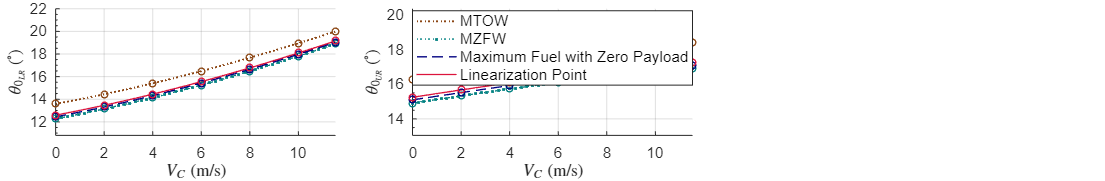

axes(ha(2));

% MTOW
plot(v_C_fine, theta_UR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_C_fine, theta_UR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_UR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_C_fine, theta_UR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_C, theta_UR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_UR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_UR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_UR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold off

% Legends
legend("MTOW", "MZFW", "Maximum Fuel with Zero Payload", "Linearization Point", "Location",  "best", 'NumColumns', 1, FontSize = 11.5)

% Axis labels with LaTeX font
xlabel('$V_{C} \; (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\theta_{0_{UR}} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
ylim([(ax.YLim(1) - ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

set(ha(3), 'Visible', 'off');

% Set figure size
set(gcf, 'Position', [0 0 1100 180]);

**2.2 Hover and forward Flight**

theta_LR

figure(2)

clf;

ha = tight_subplot(3, 3, [0.10 0.07], [0.10 0.05], [0.05 0.05]); 

axes(ha(1));

% MTOW
plot(v_F_fine, theta_LR_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, theta_LR_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, theta_LR_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, theta_LR_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, theta_LR_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, theta_LR_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, theta_LR_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, theta_LR_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
ylabel('$\theta_{0_{LR}} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) - ax.YLim(1) * 0.17), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) - ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

theta_UR

axes(ha(2));

% MTOW
plot(v_F_fine, theta_UR_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, theta_UR_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, theta_UR_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, theta_UR_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, theta_UR_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, theta_UR_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, theta_UR_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, theta_UR_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
ylabel('$\theta_{0_{UR}} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) - ax.YLim(1) * 0.25), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) - ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

theta_1s

axes(ha(3));

% MTOW
plot(v_F_fine, theta_1s_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, theta_1s_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, theta_1s_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, theta_1s_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, theta_1s_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, theta_1s_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, theta_1s_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, theta_1s_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
ylabel('$\theta_{1s} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) + ax.YLim(1) * 0.17), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) + ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

theta_1c

axes(ha(4));

% MTOW
plot(v_F_fine, theta_1c_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, theta_1c_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, theta_1c_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, theta_1c_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, theta_1c_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, theta_1c_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, theta_1c_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, theta_1c_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
ylabel('$\theta_{1c} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, 0.3, '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) + ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

phi

axes(ha(5));

% MTOW
plot(v_F_fine, phi_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, phi_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, phi_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, phi_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, phi_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, phi_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, phi_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, phi_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
ylabel('$\phi \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) - ax.YLim(1) * 0.35), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) - ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

theta

axes(ha(6));

% MTOW
plot(v_F_fine, theta_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, theta_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, theta_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, theta_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, theta_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, theta_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, theta_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, theta_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
xlabel('$V \; (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\theta \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) + ax.YLim(1) * 0.17), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) + ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

delta_E

axes(ha(7));

% MTOW
plot(v_F_fine, delta_E_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, delta_E_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, delta_E_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, delta_E_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, delta_E_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, delta_E_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, delta_E_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, delta_E_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
xlabel('$V \; (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\delta_{E} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) + ax.YLim(1) * 0.17), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) + ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off';  

delta_R

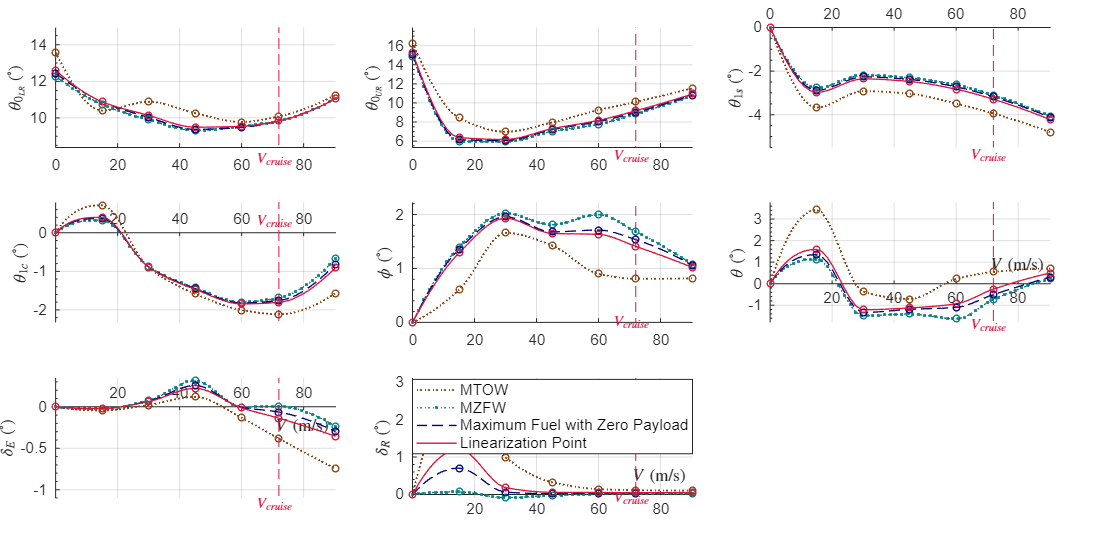

axes(ha(8));

% MTOW
plot(v_F_fine, delta_R_F_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.4)
hold on

% MZFW
plot(v_F_fine, delta_R_F_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on

% Maximum Fuel with Zero Payload
plot(v_F_fine, delta_R_F_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1)
hold on

% Linearization Point
plot(v_F_fine, delta_R_F_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on

% MTOW
plot(v_F, delta_R_F_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% MZFW
plot(v_F, delta_R_F_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_F, delta_R_F_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_F, delta_R_F_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1, 'MarkerSize', 5)
hold on

% Axis labels with LaTeX font
xlabel('$V \; (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\delta_{R} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';
text(v_F_t, (ax.YLim(1) + ax.YLim(1) * 0.17), '$V_{cruise}\;\;$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'Color', [220/255 20/255 60/255], 'FontSize', 11.5);

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
ylim([(ax.YLim(1) + ax.YLim(1) * 0.1) (ax.YLim(2) + ax.YLim(2) * 0.1)]);

% Vertical lines
plot([v_F_t v_F_t], [-50 50], '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.75)
hold off

% Legends
legend("MTOW", "MZFW", "Maximum Fuel with Zero Payload", "Linearization Point", "Location",  "best", 'NumColumns', 1, FontSize = 11.5)

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set plot limits and grid
xlim([min(v_F) max(v_F)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

set(ha(9), 'Visible', 'off');

% Set figure size
set(gcf, 'Position', [0 0 1100 550]);